M1 = 0.5;
M2 = 1.5;
L1 = 1;
L2 = 0.8;
J1 = 5;
J2 = 5;

[a1,b1,c1,d1,e1] = deal(1,-1,0.25,-1,-4);
[a2,b2,c2,d2,e2] = deal(1,1,-0.3,-1,-3);

qref = @(time,a,b,c,d,e) a + b*exp(d*time) + c*exp(e*time);
time = linspace(0,10);

figure
tiledlayout(2,1)

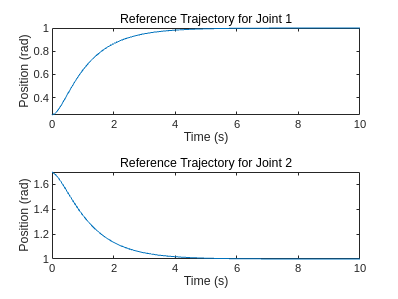


nexttile
plot(time,qref(time,a1,b1,c1,d1,e1))
title("Reference Trajectory for Joint 1")
ylabel("Position (rad)")
xlabel("Time (s)")

nexttile
plot(time,qref(time,a2,b2,c2,d2,e2))
title("Reference Trajectory for Joint 2")
ylabel("Position (rad)")
xlabel("Time (s)")

eta = [1; 3];  % Amplitude of discontinuous control action
K = [2; 1];    % Proportional gain
C = [5; 5];    % Sliding surface coefficient
D = 0;         % Disturbance estimate
Phi = 0.01;    % Boundary layer thickness
delta = 0.01;

mdl = "robotManipulatorModel";
open_system(mdl)

시스템 또는 파일 'robotManipulatorModel'을(를) 찾을 수 없습니다.

x0 = [0;0;0;0];matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'RF', 'focused', 'open_system');

variantPath = "robotManipulatorModel/SMC Controller/Variant Subsystem";
set_param(variantPath,"OverrideUsingVariant","sign");

[Md1,Md2,Ld1,Ld2,Jd1,Jd2] = deal(M1,M2,L1,L2,J1,J2);

simout = sim(mdl);

[sim1, ref] = postProcessSimResults(simout,C);

Md1 = 0.1;
Md2 = 1.0;
Ld1 = 1;
Ld2 = 0.8;
Jd1 = 4;
Jd2 = 6;

simout = sim(mdl);
sim2 = postProcessSimResults(simout,C);

figure
stackedplot(ref,sim1,sim2, ...
    ["q1","q2","qdot1","qdot2"], ...
    Title="State Trajectories");